# Lasso Secular Determinant

Computes analytical and numerical secular determinants and compares the results with each other as well as the squareroots of the eigenvalues.

### Create the graph

Creates the graph with both the uniform and Chebyshev discretizations so we can compare the eigenvalues of these two discretizations later

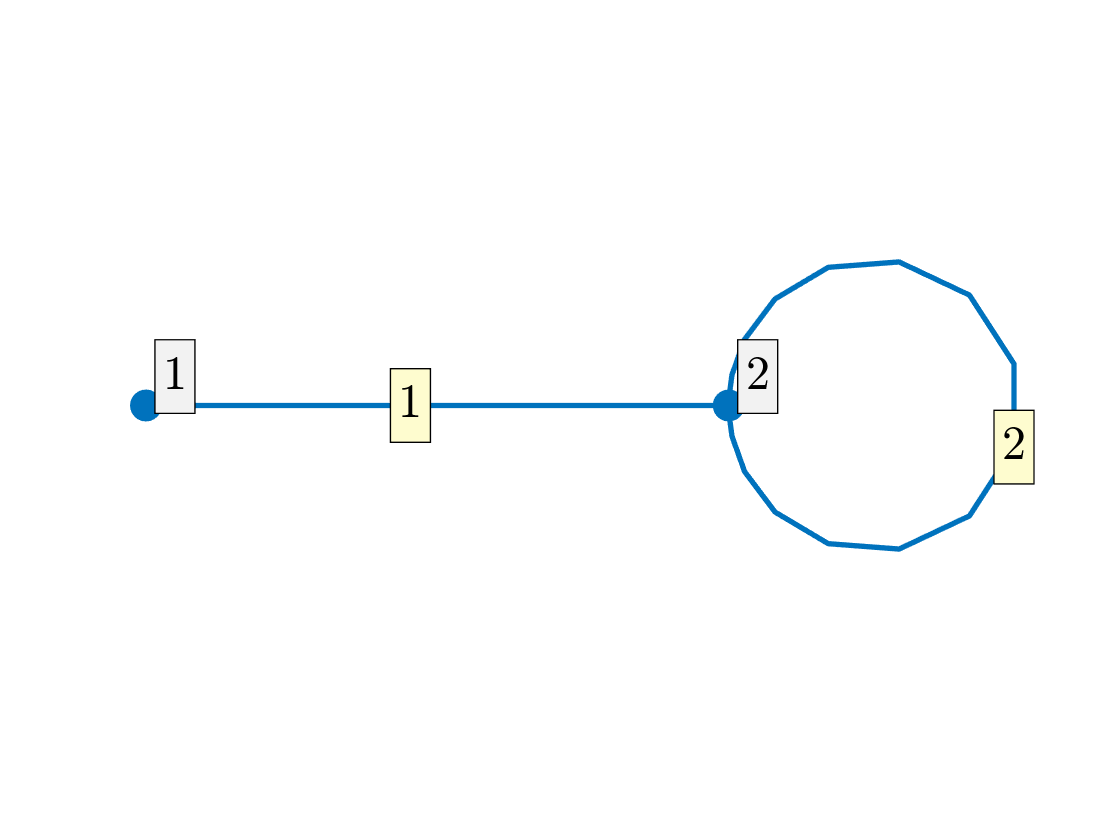

syms k
clf;
alpha = 0;  % Leaf Kirchoff condition
beta = 1;   % Interior Robin condition
robinCoeff = [alpha beta];
Phi = quantumGraphFromTemplate('nbell','nBells',1,'robinCoeff',robinCoeff,'discretization','Chebyshev','nx',16);
PhiU = quantumGraphFromTemplate('nbell','nBells',1,'robinCoeff',robinCoeff,'discretization','Uniform','nx',64);
Phi.plot('layout')

## Numerical Secular Determinant

This converts the symbolic numerical secular determinant to a Matlab function then plots it and it's zeros

[SD,S,D] = Phi.secularDet;
disp('The numerical secular determinant is:')

The numerical secular determinant is:


disp(SD)

$$\frac{2\,x\,\cos\left(2\,x\right)+\cos\left(2\,x\right)\,\sin\left(\pi \,x\right)-2\,x\,\cos\left(2\,x\right)\,\cos\left(\pi \,x\right)+x\,\sin\left(2\,x\right)\,\sin\left(\pi \,x\right)}{\sqrt{9\,x^{2}+1}}$$

(I should point out that this S matrix matches my analytic results.)

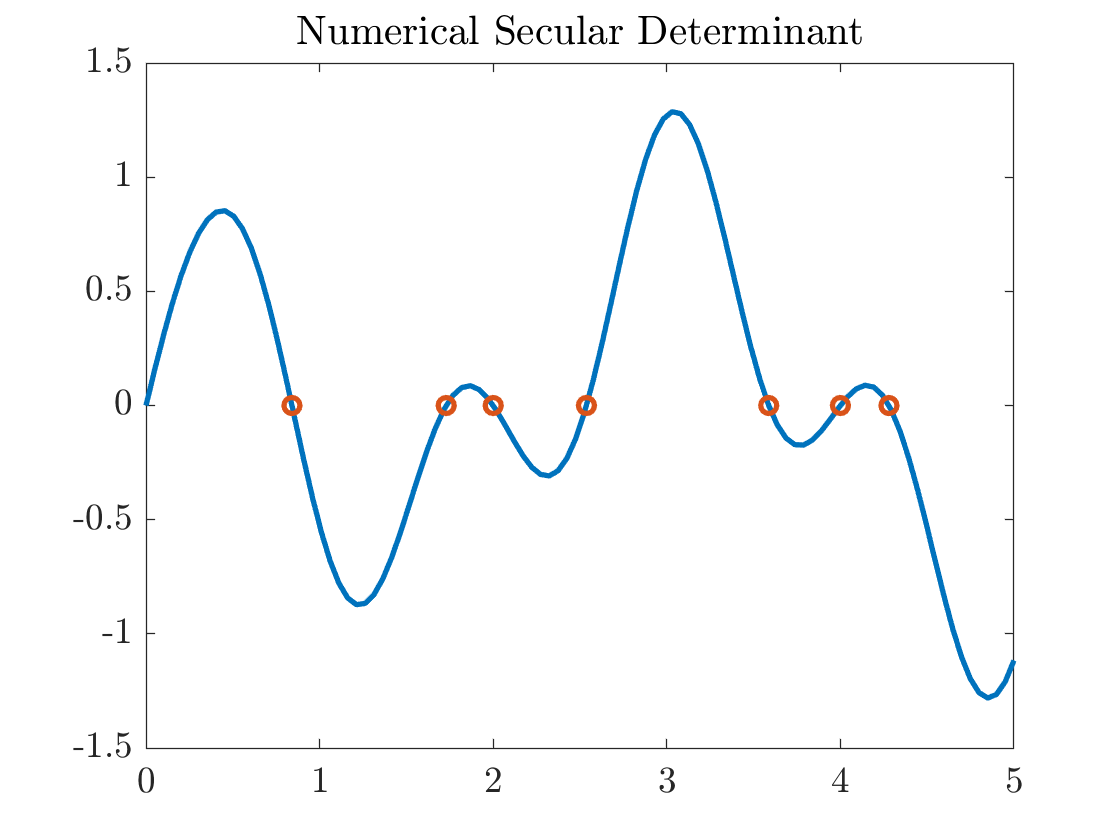

F=matlabFunction(SD);
x=linspace(0,5);
Fx=F(x);
clf
plot(x,Fx)
title('Numerical Secular Determinant')

% Finds zeros of F(x)
kmax=2;
signChanges=find(Fx(1:end-1).*Fx(2:end)<0);
nSignChanges=length(signChanges);
kstar=zeros(nSignChanges,1);
for n=1:nSignChanges
    kstar(n)=fzero(F,x(signChanges(n)+[0 1]));
end
min=islocalmin(Fx); min = find(min==1);
max=islocalmax(Fx); max = find(max==1);
minmax=union(min,max);
i=1;
doubleRoots=NaN;
for n=1:length(minmax)
    if abs(F(x(minmax(n))))<10^(-2)
        doubleRoots(i)=x(minmax(n));
        i=i+1;
    end
end
if ~isnan(doubleRoots)
    kstar = union(kstar,doubleRoots);
end
hold on
plot(kstar,zeros(size(kstar)),'o')

lambdaNumerical = kstar.^2;

## Analytical Secular Determinant

This converts the symbolic analytical secular determinant to a Matlab function then plots it and it's zeros

analyticSD = 4*sin(pi*k/2)*...
    (k*(alpha+beta)*cos(k*(-4+pi)/2)+...
    k*(beta-3*alpha)*cos(k*(4+pi)/2)+...
    3*k^2*sin(k*(4+pi)/2)-...
    k^2*sin(k*(4-pi)/2)+...
    alpha*beta*sin(k*(4+pi))+...
    alpha*beta*sin(k*(4-pi)));
disp('The analytic secular determinant is:')

The analytic secular determinant is:


disp(analyticSD)

$$4\,\sin\left(\frac{\pi \,k}{2}\right)\,\left(k\,\cos\left(\frac{2010179625846179\,k}{562949953421312}\right)+k\,\cos\left(\frac{241620187839069\,k}{562949953421312}\right)+3\,k^{2}\,\sin\left(\frac{2010179625846179\,k}{562949953421312}\right)-k^{2}\,\sin\left(\frac{241620187839069\,k}{562949953421312}\right)\right)$$

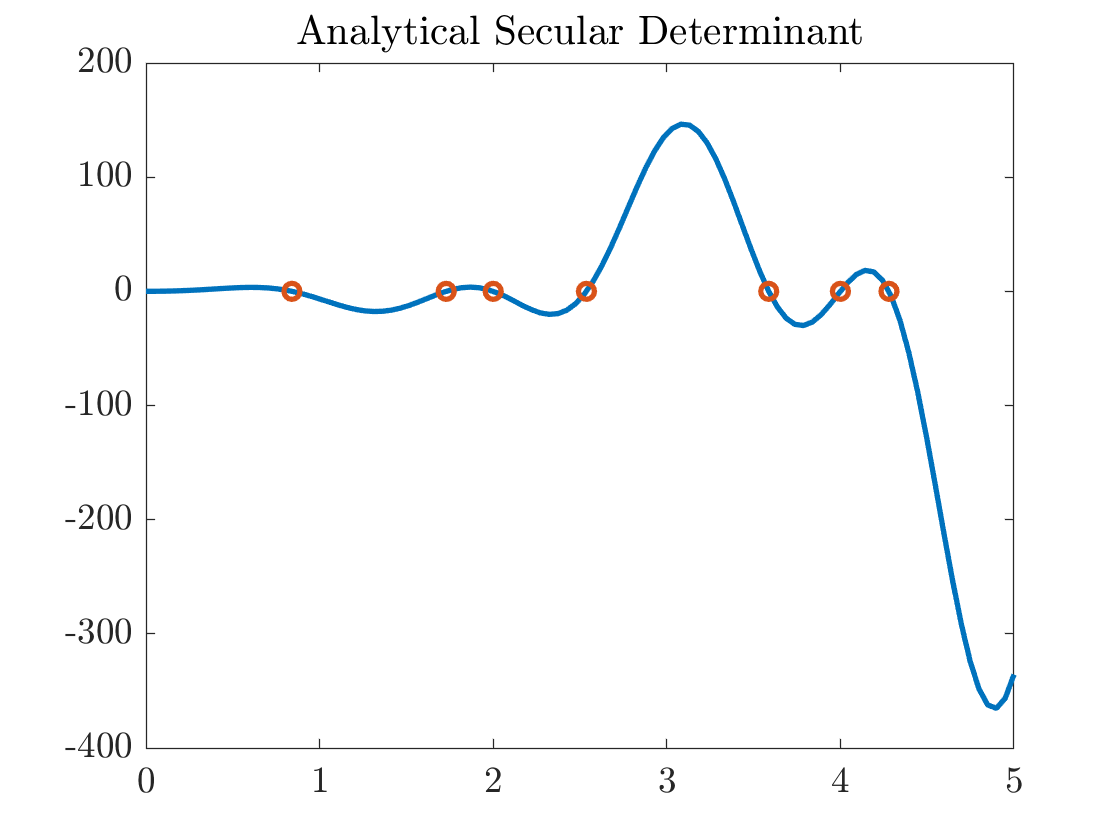

analyticF = matlabFunction(analyticSD);
analyticFx = analyticF(x);
figure
plot(x,analyticFx)
title('Analytical Secular Determinant')

% Finds zeros of F(x)
signChangesA=find(analyticFx(1:end-1).*analyticFx(2:end)<0);
nSignChangesA=length(signChangesA);
kstarA=zeros(nSignChangesA,1);
for n=1:nSignChangesA
    kstarA(n)=fzero(analyticF,x(signChangesA(n)+[0 1]));
end
m=length(kstarA);
min=islocalmin(Fx); min = find(min==1);
max=islocalmax(Fx); max = find(max==1);
minmax=union(min,max);
i=1;
doubleRoots=NaN;
for n=1:length(minmax)
    if abs(F(x(minmax(n))))<10^(-2)
        doubleRoots(i)=x(minmax(n));
        i=i+1;
    end
end
if ~isnan(doubleRoots)
    m = m + 2*length(doubleRoots);
    kstarA = union(kstarA,doubleRoots);
end
hold on
plot(kstarA,zeros(size(kstarA)),'o')

lambdaAnalytic = kstarA.^2;

We then create a plot comparing the two secular determinants and their roots.

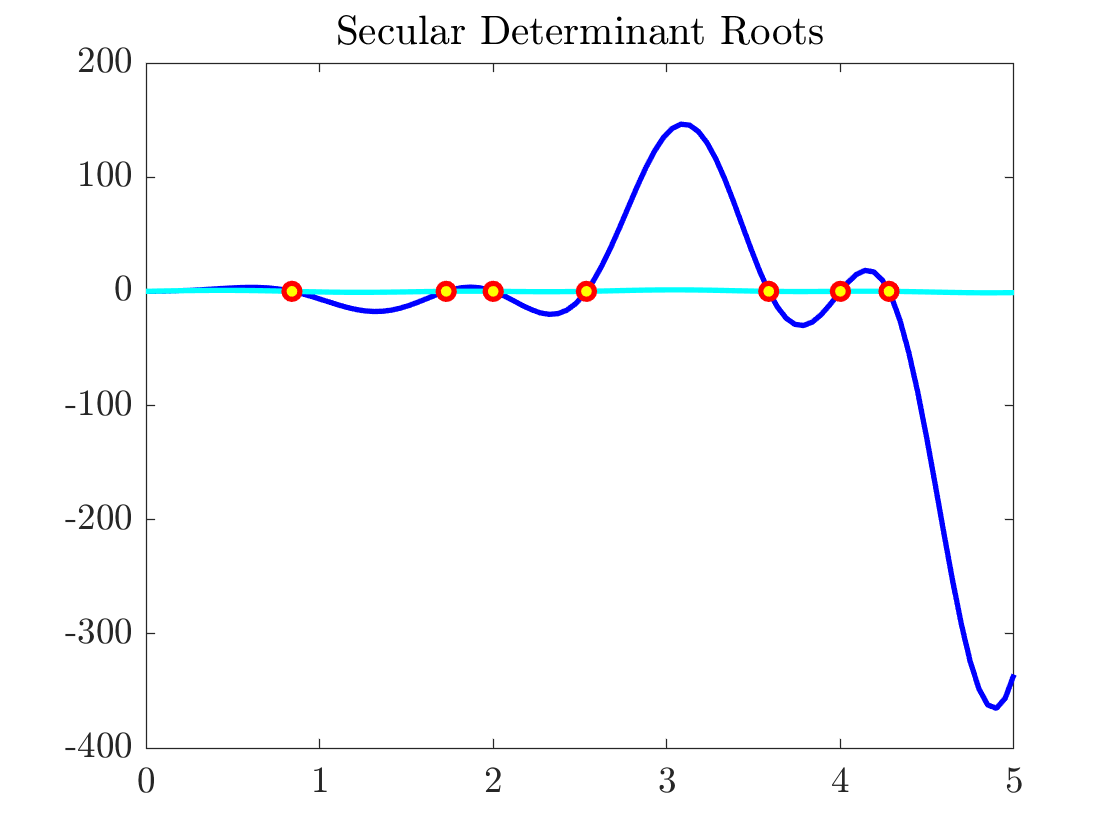

figure
plot(x,analyticFx,'color','b')
title('Secular Determinant Roots')
hold on
plot(x,Fx,'color','cyan')
hold on
plot(kstar,zeros(size(kstar)),'*','color','y')
hold on
plot(kstarA,zeros(size(kstarA)),'o','color','r')

## Compares secular determinant to Laplacian eigenvalue

Table of found lambda values. The column labels are shorthand for:

NSD: evals from the numerical SD

ASD: evals from the analytical SD

Cheb: evals from Chebyshev Laplacian

Uni: evals from uniform Laplacian

[~,lambda] = eigs(Phi,m+1);
lambda = uniquetol(lambda);
lambda = lambda(2:end);
sqrt(lambda);
[~,lambdaU] = eigs(PhiU,m+1);
lambdaU = uniquetol(lambdaU);
lambdaU = -flip(lambdaU(2:end));
sqrt(lambdaU);

A = [lambdaNumerical'; lambdaAnalytic'; lambda'; lambdaU'];

T = array2table(A','VariableNames', ...
    {'NSD','ASD','Cheb','Uni'})

T = 7×4 table
     NSD       ASD       Cheb       Uni  
    ______    ______    ______    _______

    0.7067    0.7067    0.7067      0.271
    2.9901    2.9901    2.9901    0.73992
         4         4         4     3.9224
    6.4369    6.4369    6.4369     3.9997
    12.867    12.867    12.867     6.7317
        16        16        16     13.415
    18.316    18.316    18.316     15.995


Compare zeros of SD (represented on plot) to the sqrt of the evals. They should be the same!

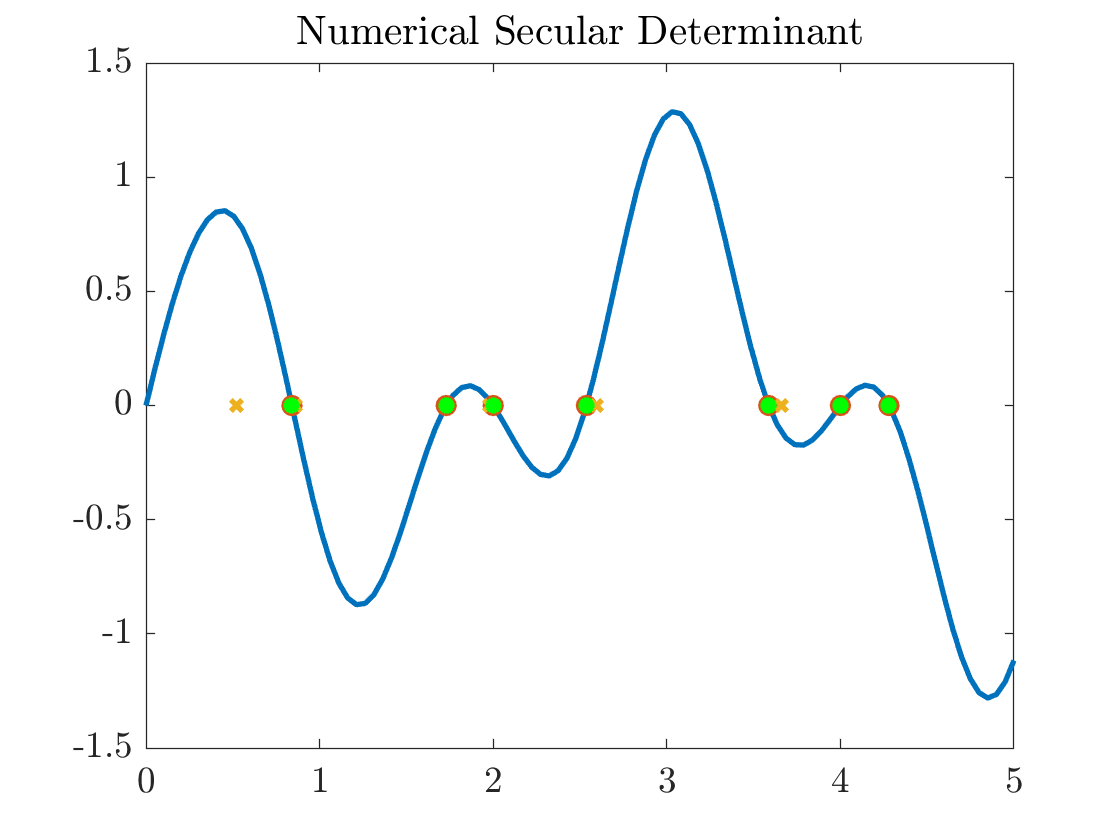

figure
plot(x,Fx)
title('Numerical Secular Determinant')
hold on
plot(kstar,zeros(size(kstar)),'o')
hold on
plot(sqrt(lambdaU),zeros(size(lambdaU)),'x')
hold on
plot(sqrt(lambda),zeros(size(lambda)),'*','color','g')

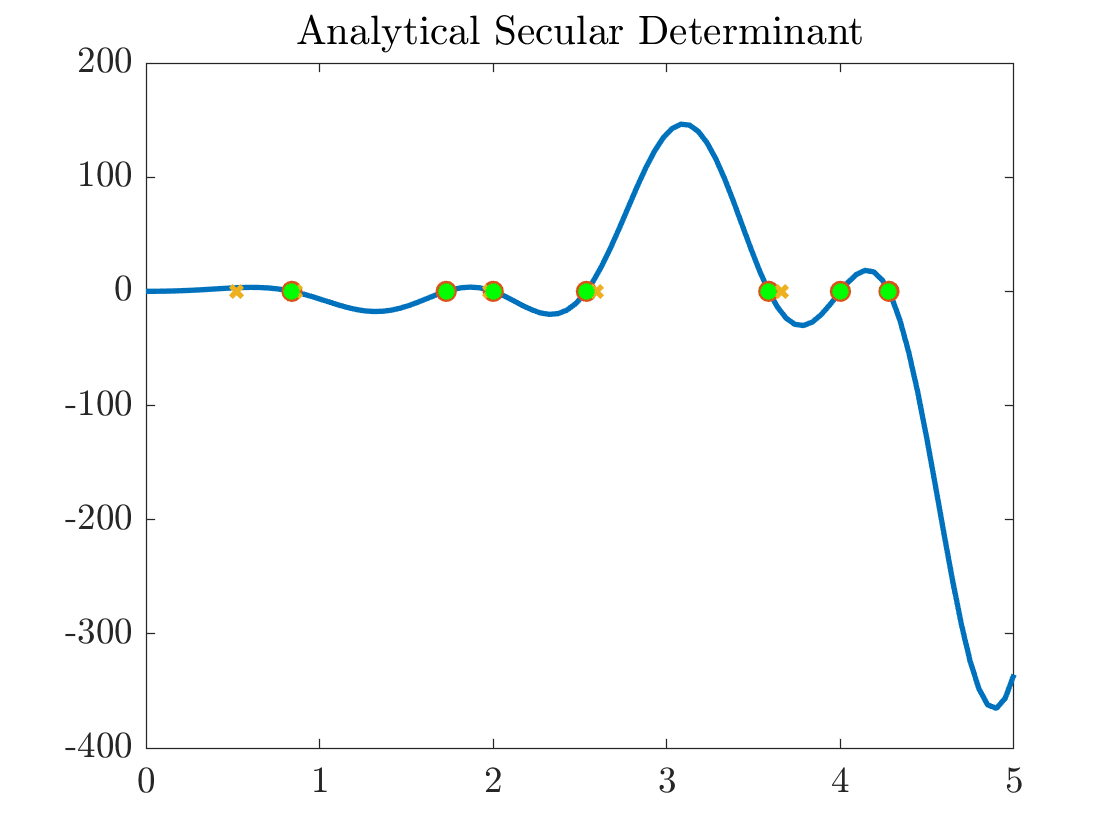



figure
plot(x,analyticFx)
title('Analytical Secular Determinant')
hold on
plot(kstarA,zeros(size(kstarA)),'o')
hold on
plot(sqrt(lambdaU),zeros(size(lambdaU)),'x')
hold on
plot(sqrt(lambda),zeros(size(lambda)),'*','color','g')